# Module 2: Action Functional Gradient Descent (AFGD) algorithm

clear all

## Load model

lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_2"

plotnam = "2-Schlogl"

plotnam = "2-Schlogl"

model_name = "Selkov"

model_name = "Selkov"

plotnam = "Selkov"

plotnam = "Selkov model"

model_name = "SYN3_FINAL"
plotnam = "12-D Syntrophy model"

model_name = "Cluster_3_catalyst"
plotnam = "3-D Cluster model with catalysis"

model_name = "Cluster_3_catalyst_w_temp"
plotnam = "3-D Cluster model with catalysis & templating"

#### Load ..._Ham.mat from 'data' folder

load('..\Data\'+model_name+'_Ham.mat')

#### Load heteroclinic network

i = row in hc_net. j = column in hc_net - 1 

load('..\Data\' + model_name + '_hcnet.mat')
pos_root_arr

$$pos\_root\_arr = \left(\begin{array}{cc} 1 & 1\\ 2 & 2\\ 2.1654 & 1.0930\\ 1.0930 & 2.1654\\ 2.8367 & 1.1633\\ 1.1633 & 2.8367\\ 3 & 3\\ 2.9070 & 1.8346\\ 1.8346 & 2.9070 \end{array}\right)$$

hc_net

hc_net =      3     5     1
     4     6     1
     8     7     5
     9     7     6


i = 1; j = 1;
sad_pt = i; stab_pt_choice = j;

i = 1; j = 2;
sad_pt = i; stab_pt_choice = j;

#### Load initial condition

Straight 

load('..\Data\' + model_name + '_initcond_'+string(i)...
        +'_'+string(j)+'straight.mat')

Error using load
Unable to read file '..\Data\Schlogl_1_2_initcond_21_2straight.mat'. No such file or directory.

Spiral

load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat')

#### Sample space uniform and plot

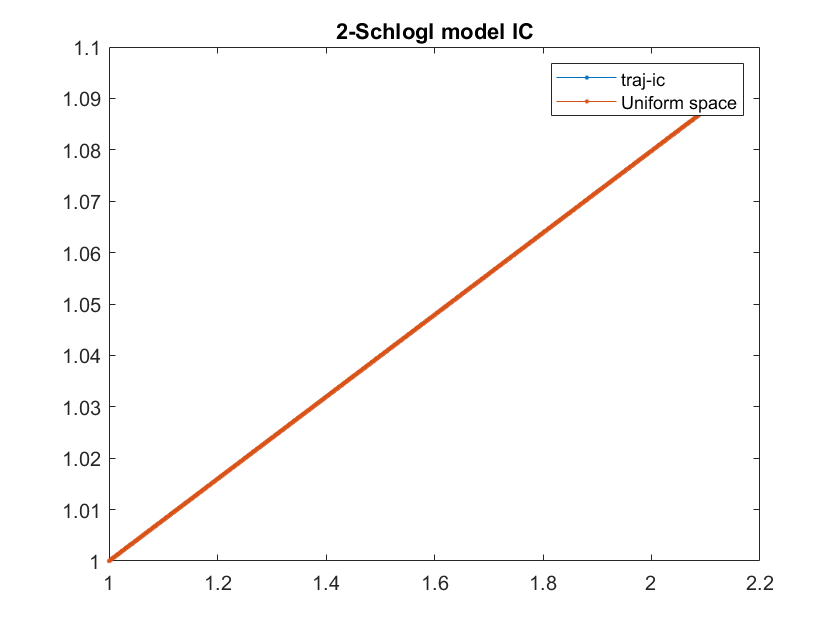

%Space uniform sampling
traj_pts = 2000;
traj_ic = double(traj_ic);
[traj,len_curve_prime] = space_uniform_sampling(traj_ic,traj_pts);
%Plot
figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')
hold on
plot(traj(:,1),traj(:,2:end),'.-')
hold off
legend('traj-ic','Uniform space')
title(plotnam + ' IC')

#### Load from existing data

save('traj_n_s_2000_Schlogl.mat',"traj_n_s")

load('traj_n_s_2000_Schlogl.mat')
traj = traj_n_s; traj_pts = size(traj,1);
[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);

## Initialize Descender

%number of points in trajectory
traj_pts = size(traj,1);

%Initialize arrays for saving and delta_x_s
Initialize_descender

S_arr = 0.0168


%Save data to file in the data folder
savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'straight_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "..\Data\Schlogl_1_2_descend_1_2straight_3000_09-Jul-2022.mat"

%Save data to file in the data folder (for spiral)
%savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
%+'_'+string(stab_pt_choice)+'spiral_'+string(traj_pts)+'_'+string(date)+'.mat'

%Plot PS_traj and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_PS_traj_IC.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_PS_traj_IC.png"

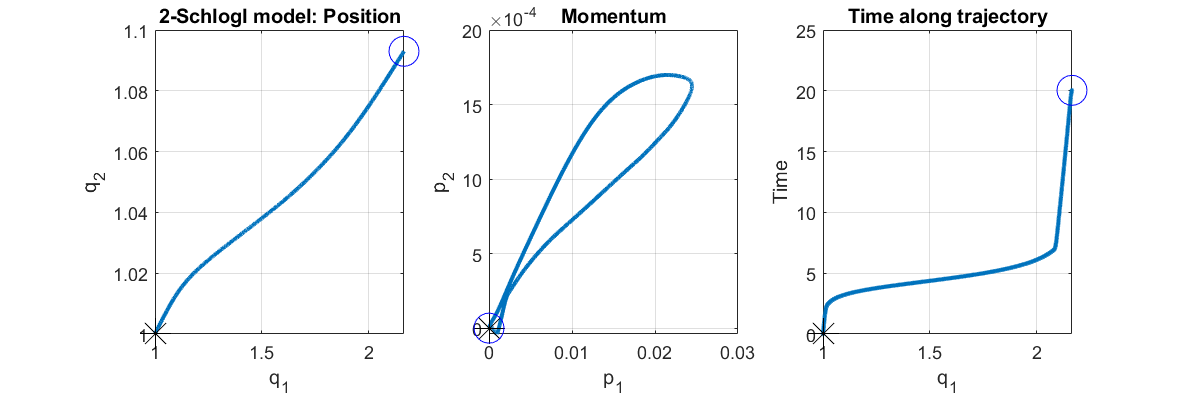

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax_IC.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax_IC.png"

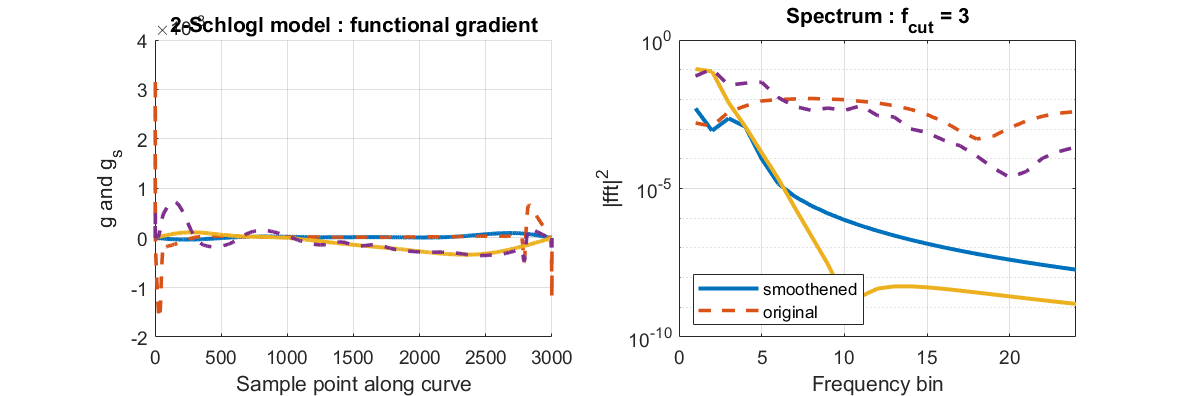

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

## Actual descent

%Actual descender
eps_ic = 1; eps = eps_ic;
delta_S = 10; err_thresh = 10^(-1); 
f0_max = 40; f0_step = 0.1; 
eps_S_thresh = 10^(-9); delta_S_thresh = 10^(-8);
iter_max = 10; iter = 1;

f0 = 6.5;

iter_max = 38;

ans =   36.000000000000000                   0   0.016802290594465                   0  10.000000000000000


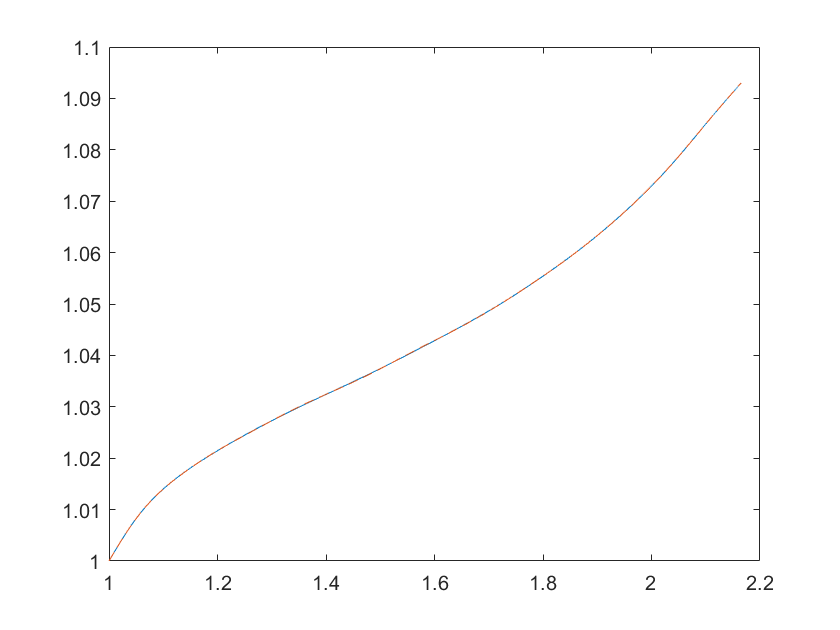

format long
while f0<f0_max  &&  iter<iter_max
    iter = iter + 1;
    
    %smoothen gradient(gradient @ I-1)
    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]

    %if delta_S is positive, then break. If less than threshold then
    %increase cutoff frequency
    if delta_S > 0
        disp('Why is action increasing? Error!')
        break
    elseif eps == 0
        f0 = f0+0.1; eps = 1; delta_S = 1;  
        traj_pts_new = traj_pts;
        traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        %[traj,len_curve_prime] = space_uniform_sampling(traj_n_s,traj_pts);
        %[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    elseif abs(delta_S)<delta_S_thresh || eps < 0.01
        f0 = f0 + 0.1; eps = 1; delta_S = 1;  
    end

    %{
    %Optimal resampling
    [traj_prime,len_curve_prime] = optimal_resampling(traj,delta_x,f0);
    [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj_prime,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    %}
    %Smoothen gradient
    delta_x_s =  smooth_traj_butter(delta_x,f0); 
    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,5)==0
        save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_deltax_'+string(iter)+'.png'
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
    end

    
end

format short

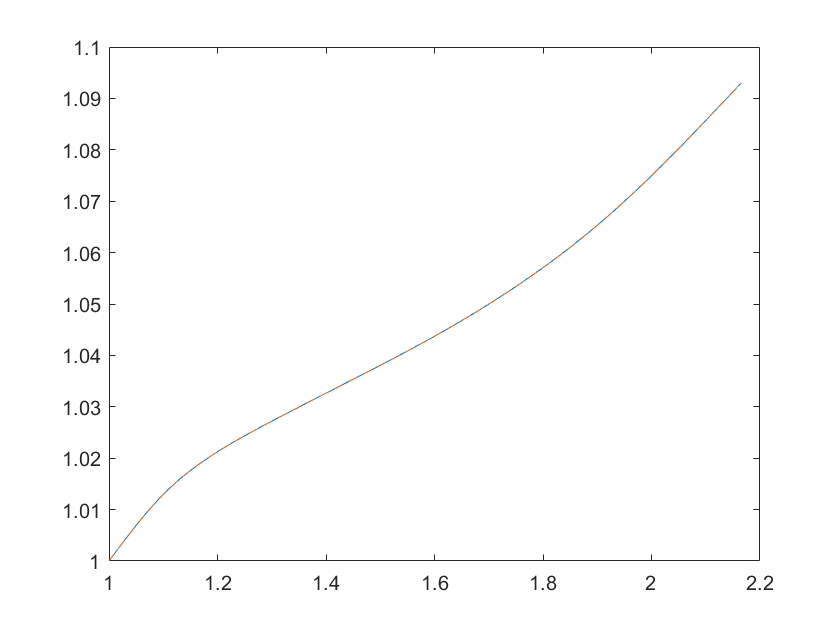

traj_pts_new = traj_pts+1000;
traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,35);

%Plot PS_traj and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_PS_traj'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_PS_traj10.png"

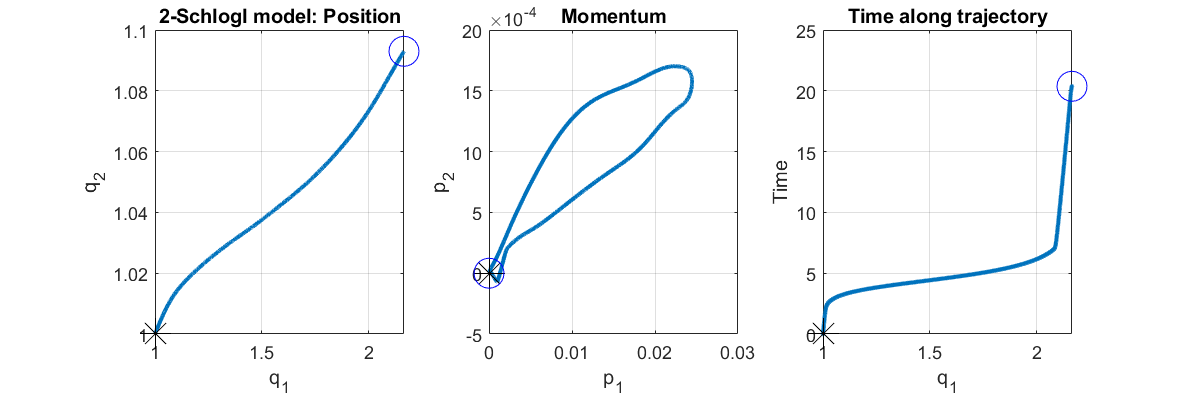

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax100.png"

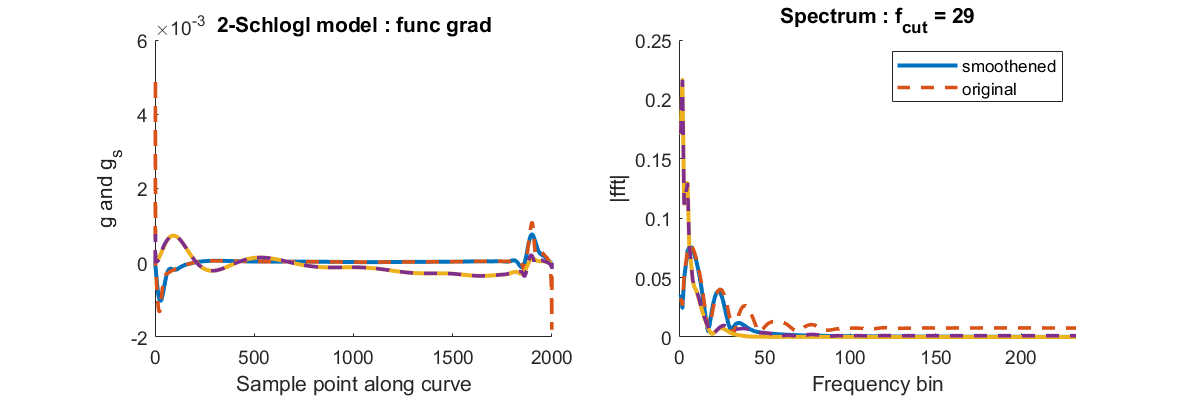

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax106.png"

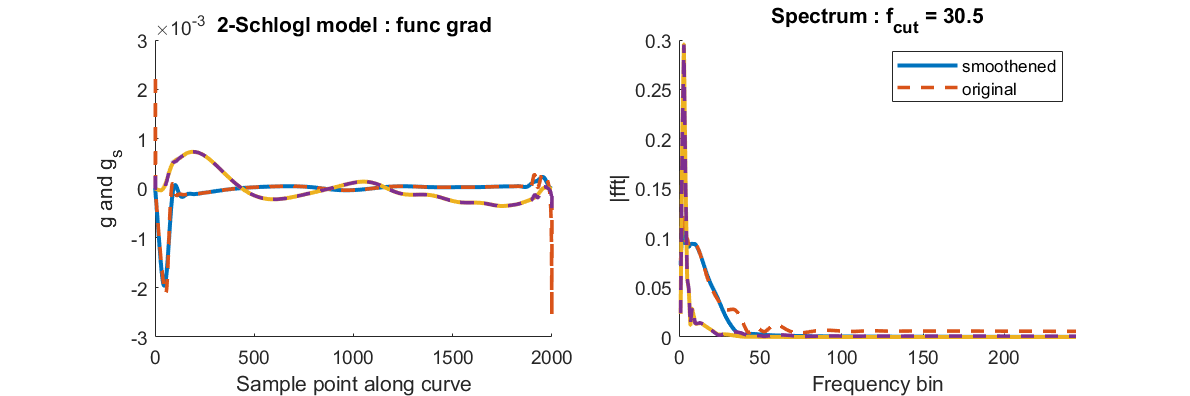

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax109.png"

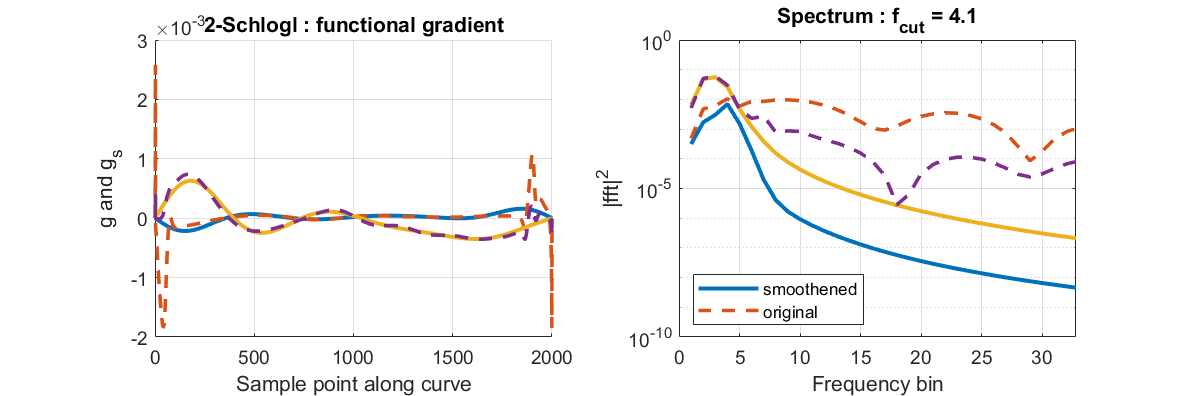

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

savenam

savenam = "..\Data\Schlogl_1_2_descend_1_2straight_2000_09-Jul-2022.mat"

delta_x(3,:)

ans = 	1.0e+-3 *

   -0.0681    0.1228


[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);


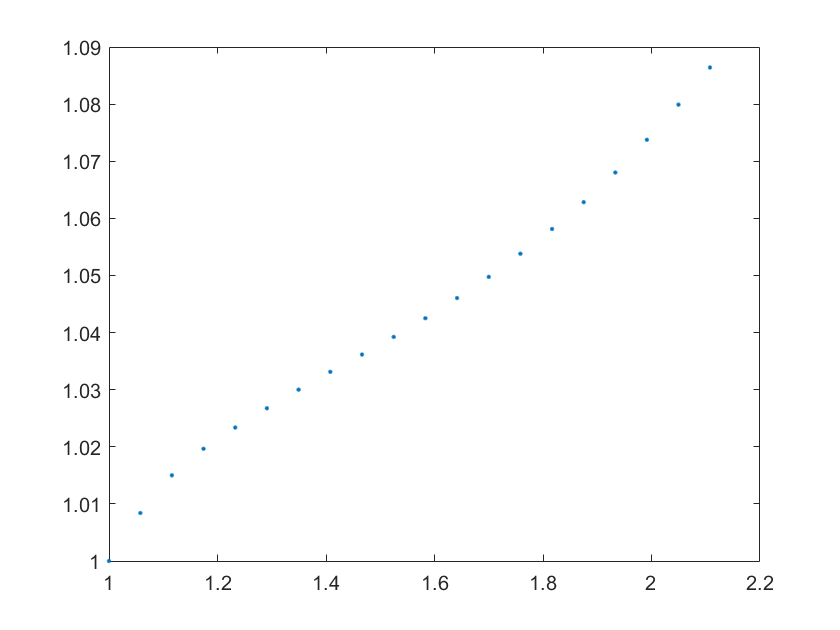

figure()
plot(traj(1:100:end,1),traj(1:100:end,2),'.')

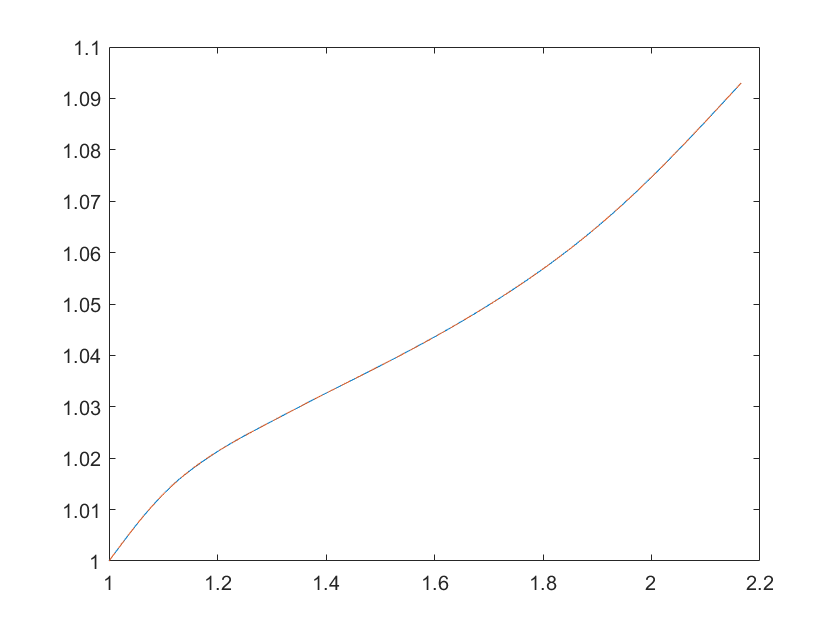

traj_pts_new = traj_pts;
traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj_n_s,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

figure()
plot(traj_n_s(:,1),traj_n_s(:,2))
hold on
plot(traj(:,1),traj(:,2),'--')
hold off

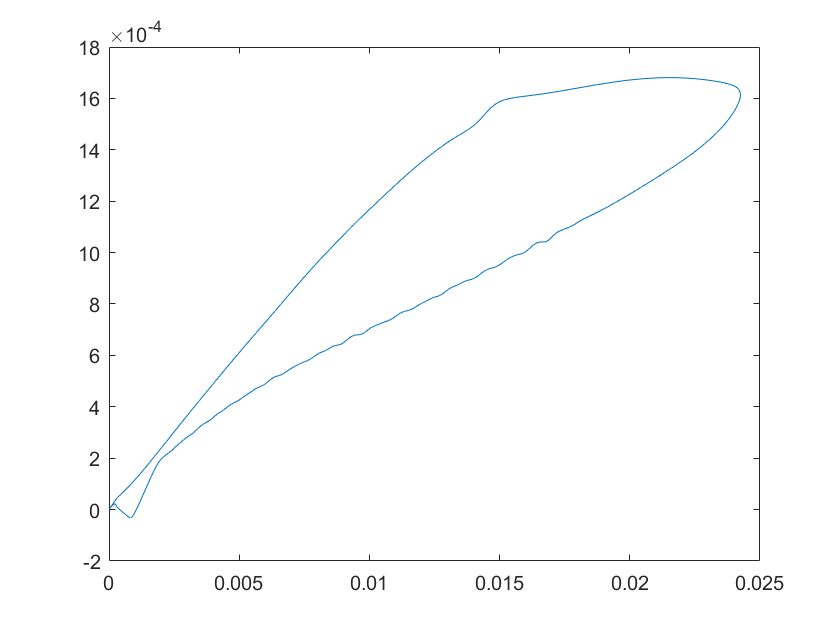

figure()
plot(PS_traj(:,3),PS_traj(:,4))  